% Live Script

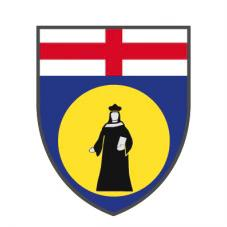

## **UNIVERSITA DEGLI STUDI DI GENOVA**

## **BIOMEDICAL FOR ROBOTICS**

## **Assignment 3 - Phantom Robot**

DIBRIS

DEPARTMENT OF COMPUTER SCIENCE AND

TECHNOLOGY, BIOENGINEERING, ROBOTICS

AND SYSTEM ENGINEERING

Authors

Davide Pisano, Miriam Anna Ruggero, Terrile Ivan

December 2023

## 1 - Reaching Task

#### *Introduction:*

The objective of this part of the assignment is to implement a Reaching Task for a Phantom Omni Haptic Device using Simulink and Stateflow. The Reaching Task is designed to be executed as follows:

- a random target will be spawned from 8 possible targets, arranged on a circumference of 10 cm with a 45° angle between each target.

- starting from the central position (0, 0), the cursor must reach the first spawned target.

- once the cursor reaches the center of the target, its color should change.

- if the cursor stays on the center of the target for 1 second, the target should fade away and reappear at the central position (0, 0).

- subsequently, the central target must be reached, and upon reaching it, its color will change.

- after pausing for 2 seconds on the central target, it will disappear, and the process will repeat for a total of 10 iterations.

- the task will conclude after reaching all 10 targets and returning to the central position (0, 0).

For this part, two implementations have been created:

- *Reaching_Simulation.slx*, which allows using the PC mouse to control the simulation;

Reaching_Simulation

- *Reaching_Phantom.slx* enables the use of the Phantom Omni Haptic Device to control the simulation cursor.

Reaching_Phantom

In both implementations, the file *2_ball_color.wrl *has been used as a model to animate a virtual environment where the targets and the cursor are displayed.

#### Simulation Implementation:

For this implementation, there are two inputs: the Mouse Control block, which enables the use of the mouse as a cursor in the simulation, and an Angles List vector containing 8 elements, each corresponding to a portion of the angle obtained by dividing the circumference into eight parts. These inputs enter a State Machine Logic block created with Stateflow, where all the previously described logic for the Reaching Task is implemented. 

The State Machine Logic block produces three outputs: the target position, the target color, and the simulation stop signal. The first two enter the VRSink simulation block along with the cursor position obtained from the Mouse Control block, enabling visualization of the Reaching Task simulation. The third signal is used to terminate the simulation after reaching all 10 targets and returning the cursor to the central position.

#### **Phantom Omni Implementation:**

For the second implementation, the structure is analogous to the previous one, with the only difference being that the Mouse Control block is replaced by the Phan Torque 3dof block. This block allows the use of the Phantom Omni Haptic Device to move the cursor within the simulation. 

To achieve this, the "Phan Torque 3dof" block takes a [0, 0, 0] vector as input and outputs the Cartesian Position of the end-effector, representing the cursor's position.

## 2 - Force Fields

#### *Introduction: *

The objective of this second part of the assignment is to create two force fields, one related to the position and one related to the velocity of the Phantom Omni Haptic Device's end-effector. The position-related field will be an attractive force field, with the function of pulling the cursor towards the target. The second one will be a viscous field that opposes the velocity of the end-effector. 

For this part, a single implementation has been created in the file *ForceField_Phantom.slx*.

ForceField_Phantom

#### *Phantom Omni Implementation:*

In this implementation, the Phan Torque 3dof block is used to control the manipulator.

The attractive field is implemented by using the Cartesian Position of the end-effector returned by the "Phan Torque 3dof" block and the Target Position to calculate the error. This error is then multiplied by a 3x3 matrix, which is diagonally positive with the z-component nullified (since the simulation operates in 2 dimensions).

On the other hand, the viscous field is implemented by using the Joint Position vector as an input for a Describe Derivative block, which calculates the velocity from the position. This velocity then enters a Discrete Transfer function and is subsequently multiplied by a 3x3 matrix with the z-component nullified.

## 3 - Force Field and Reaching Task

Beyond the previous implementations, we have developed an implementation that combines the Force Field and the Reaching Task. In this way, it is possible to perform the Reaching Task with the assistance of both the attractive and viscous Force Fields. 

This implementation is located in the file *ForceField_and_Reaching_Phantom.slx*.

ForceField_and_Reaching_Phantom

## 4 - Questions and Comments

***Q1***: To implement an attractive field, you follow the steps described above. Instead, in the case where you want to implement a repulsive field, the only modification to be made is to use a matrix F like the one described above but with negative values on the main diagonal. These types of force fields are used to assist users of the Phantom Omni Haptic Device or similar devices in reaching a specific target with greater precision if attractive. Conversely, the repulsive field is used when simulating a form of resistance to reaching the target. A possible application could be in the medical field to simulate a surgical operation.

***Q2***: To implement a viscous field, you follow the steps described above. A viscous field allows for more precise movements, eliminating unwanted tremors or oscillations.

***Comments***: The considerations drawn after numerous laboratory tests using the Phantom Omni Haptic Device and Touch X are as follows:

- values in the matrices for attractive and viscous force fields begin to generate the desired effects from values above approximately 10.

- optimal results are obtained for values around 40-60 when considering the fields individually.

- in our implementation, we use both the attractive and viscous force fields simultaneously, so we set the values to about half of the optimal values (~25).

## **5 - **Photos of the Devices

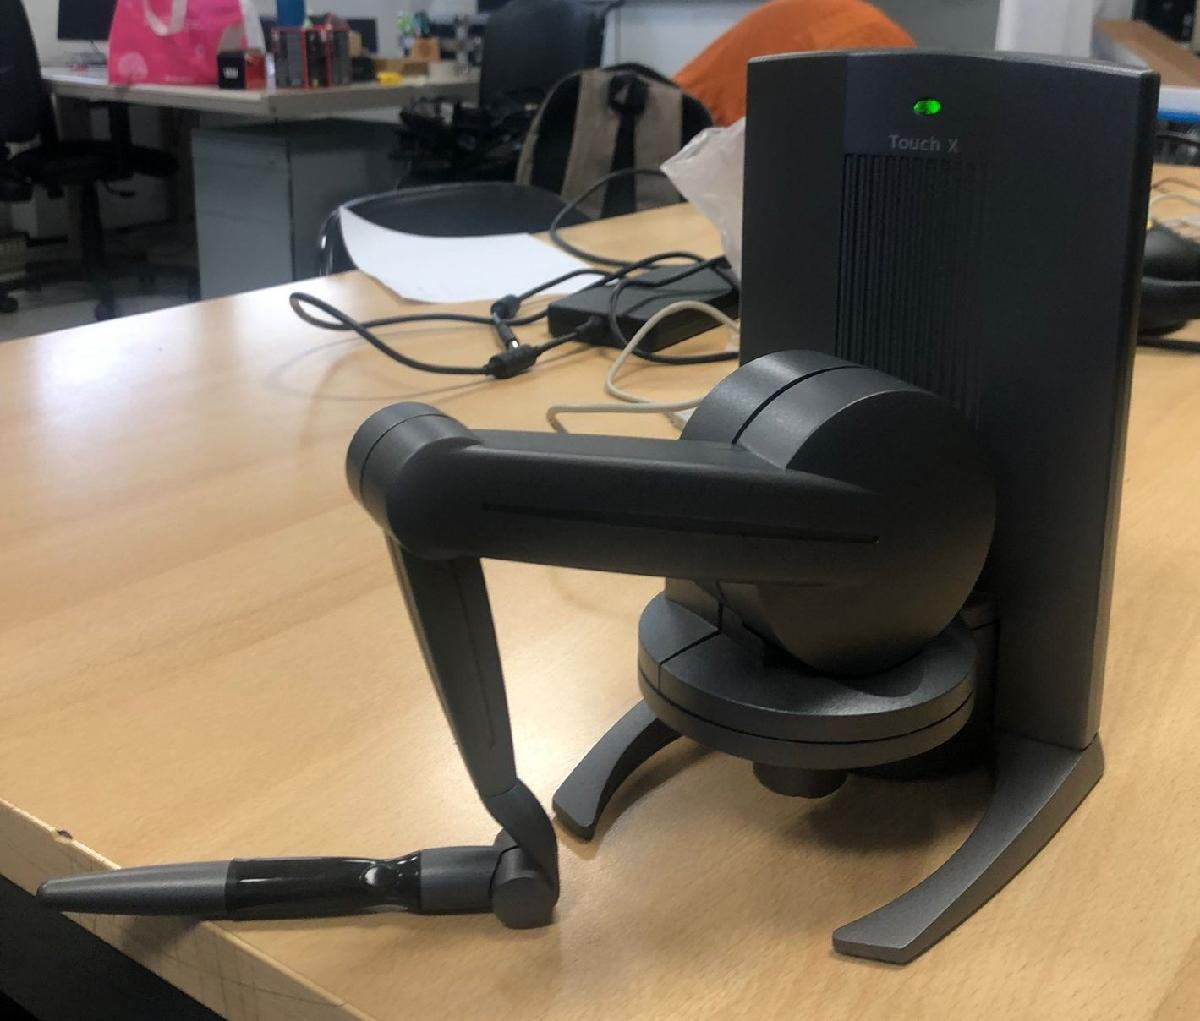          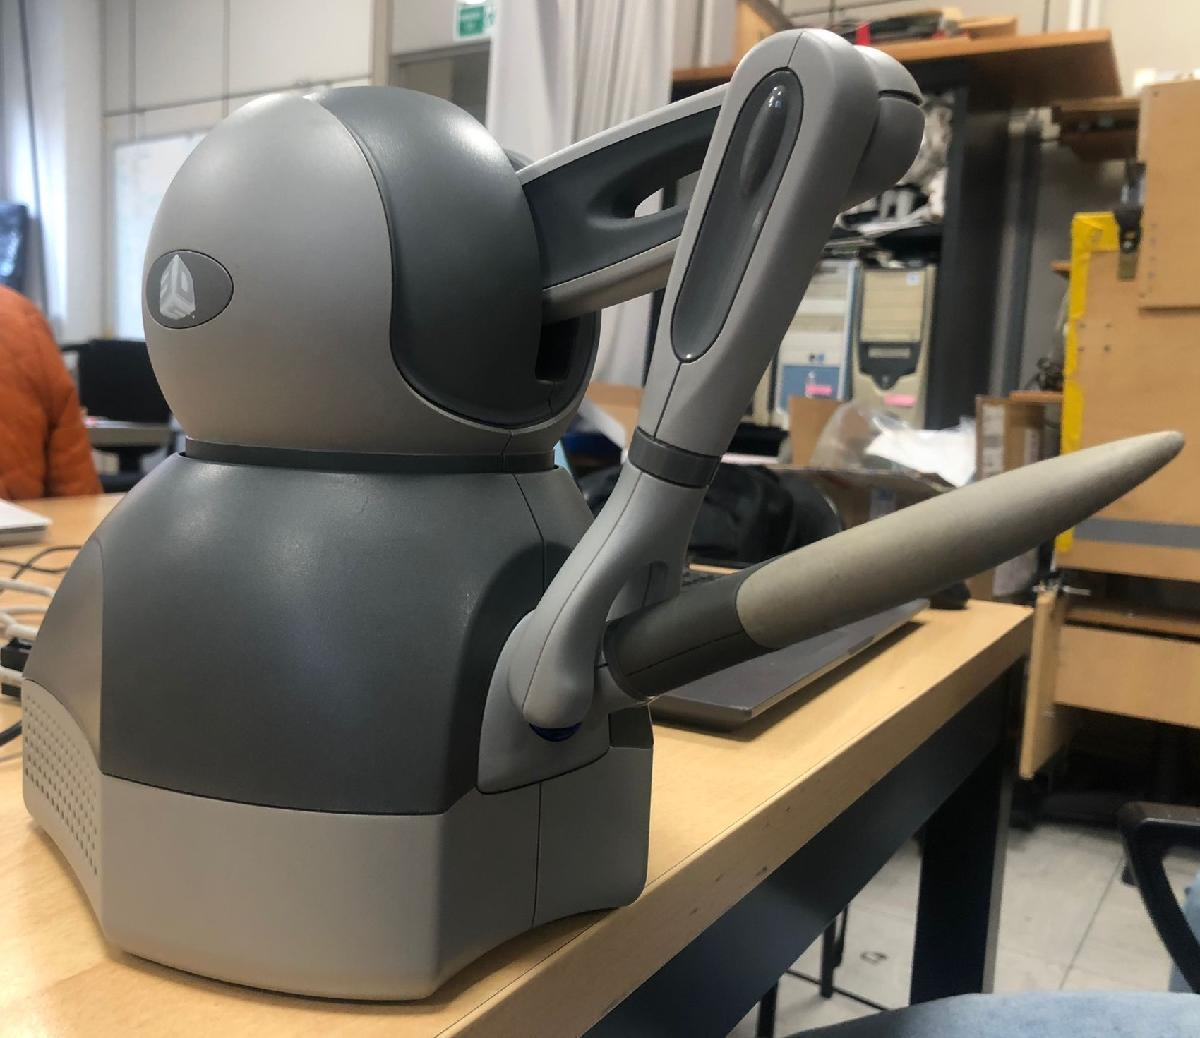

                                        Touch X                                                             Phantom Omni 